%Kai Jin
%Time:

low_data = h5read("data_lowLumi_pt_1000_1200.h5",'/data/block0_values');
high_data = h5read("data_highLumi_pt_1000_1200.h5",'/data/block0_values');
higgs_data = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');h5disp("qcd_100000_pt_1000_1200.h5")

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


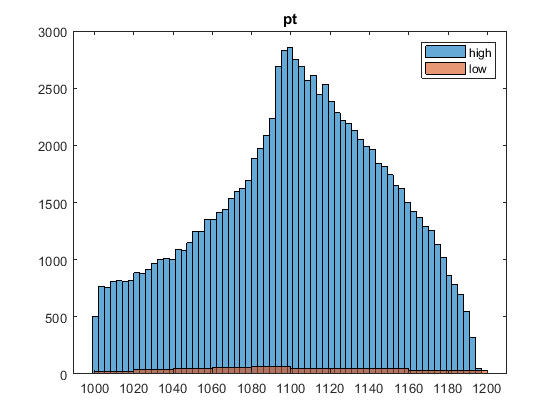

qcd_data = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

high_pt = higgs_data(1,:);
high_eta = high_data(2,:);
high_phi = high_data(3,:);
high_mass = high_data(4,:);
high_ee2 = high_data(5,:);
high_ee3 = high_data(6,:);
high_d2 = high_data(7,:);
high_angul = high_data(8,:);
high_t1 = high_data(9,:);
high_t2 = high_data(10,:);
high_t3 = high_data(11,:);
high_t21 = high_data(12,:);
high_t32 = high_data(13,:);
high_Kt = high_data(14,:);

low_pt = low_data(1,:);
low_eta = low_data(2,:);
low_phi = low_data(3,:);
low_mass = low_data(4,:);
low_ee2 = low_data(5,:);
low_ee3 = low_data(6,:);
low_d2 = low_data(7,:);
low_angul = low_data(8,:);
low_t1 = low_data(9,:);
low_t2 = low_data(10,:);
low_t3 = low_data(11,:);
low_t21 = low_data(12,:);
low_t32 = low_data(13,:);
low_Kt = low_data(14,:);

figure()
histogram(high_pt)
hold on
histogram(low_pt)
title('pt')
legend('high','low')

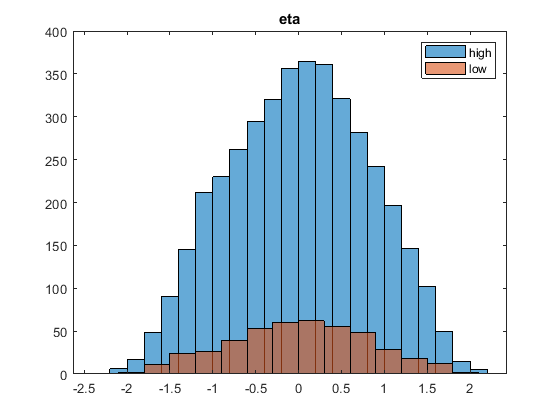


figure()
histogram(high_eta)
hold on
histogram(low_eta)
title('eta')
legend('high','low')

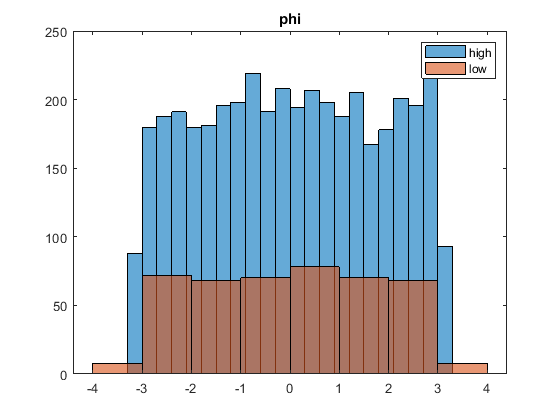


figure()
histogram(high_phi)
hold on
histogram(low_phi)
title('phi')
legend('high','low')

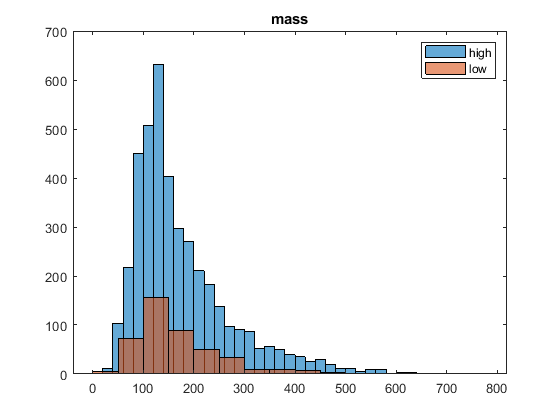


figure()
histogram(high_mass)
hold on
histogram(low_mass)
title('mass')
legend('high','low')

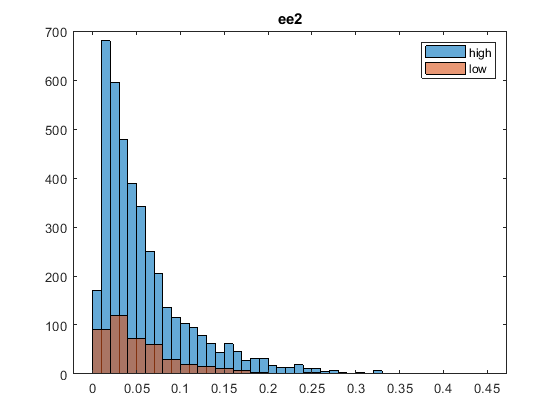


figure()
histogram(high_ee2)
hold on
histogram(low_ee2)
title('ee2')
legend('high','low')

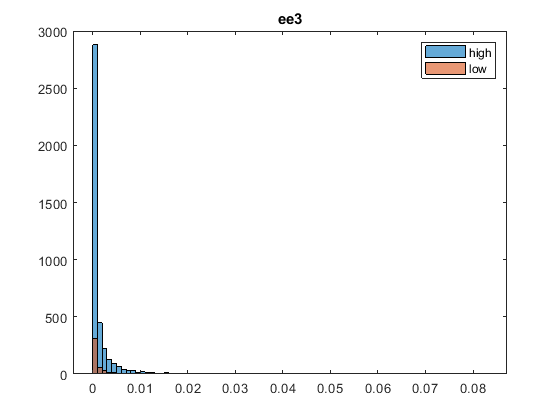


figure()
histogram(high_ee3)
hold on
histogram(low_ee3)
title('ee3')
legend('high','low')

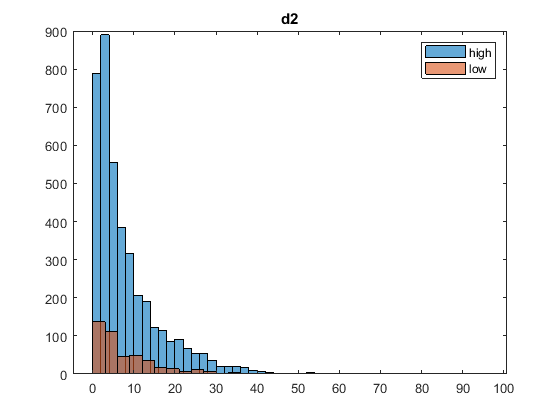


figure()
histogram(high_d2)
hold on
histogram(low_d2)
title('d2')
legend('high','low')

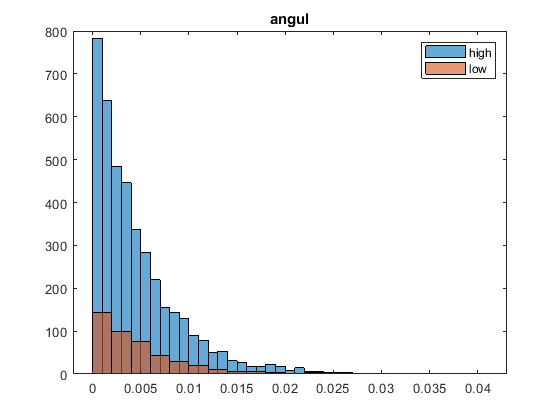


figure()
histogram(high_angul)
hold on
histogram(low_angul)
title('angul')
legend('high','low')

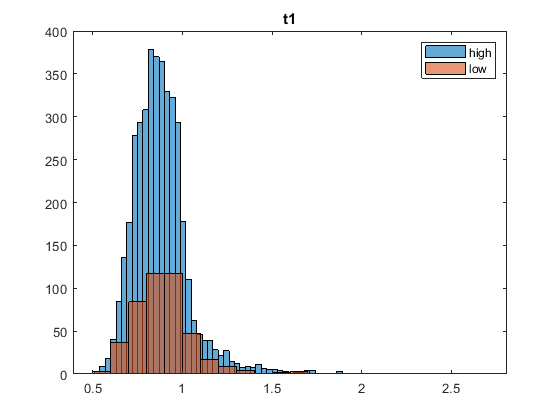


figure()
histogram(high_t1)
hold on
histogram(low_t1)
title('t1')
legend('high','low')

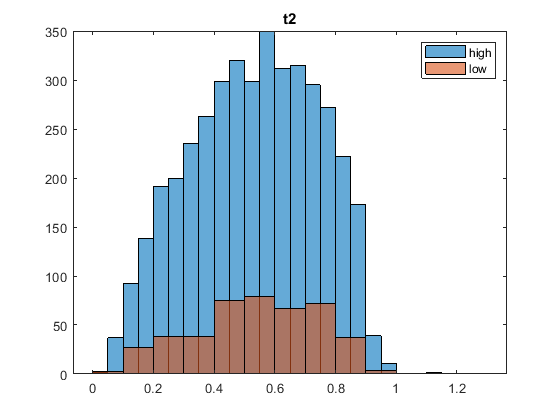


figure()
histogram(high_t2)
hold on
histogram(low_t2)
title('t2')
legend('high','low')

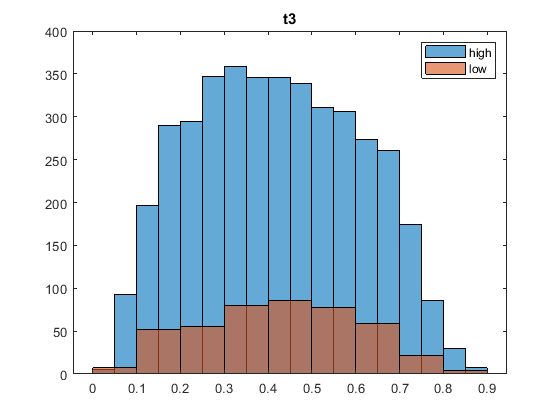


figure()
histogram(high_t3)
hold on
histogram(low_t3)
title('t3')
legend('high','low')

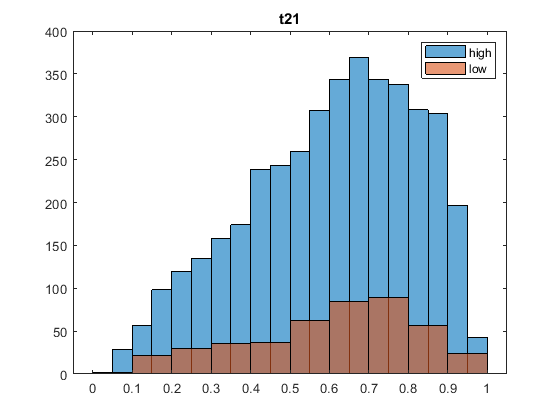


figure()
histogram(high_t21)
hold on
histogram(low_t21)
title('t21')
legend('high','low')

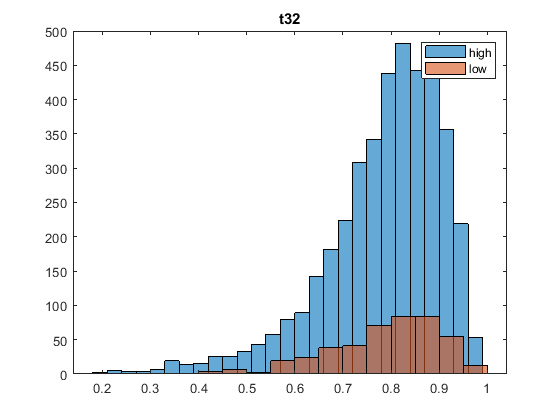


figure()
histogram(high_t32)
hold on
histogram(low_t32)
title('t32')
legend('high','low')

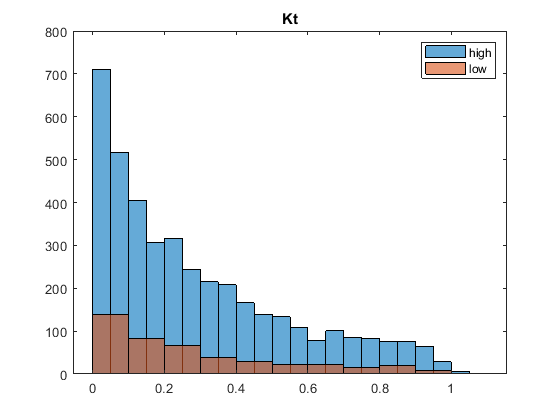


figure()
histogram(high_Kt)
hold on
histogram(low_Kt)
title('Kt')
legend('high','low')

%Based on these graph, ee3 has a significant difference between high and
%low lumi
%Therefore, I choose ee3 of pseudo-experiment as observed data, its lambda
%of poisson distribution as expected signal value and ee3 of qcd as
%background

%For low lumi data
lambda = fitdist(higgs_data(6,:).','Poisson').lambda;
figure()
histogram(low_ee3)
hold on
xline(lambda)

ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 2.1114e-04
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


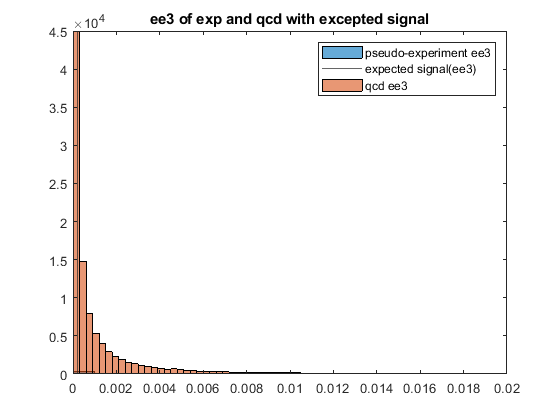

hold on
qcd_ee3 = qcd_data(6,:);
histogram(qcd_ee3)
xlim([0 0.02])
title('ee3 of exp and qcd with excepted signal')
legend('pseudo-experiment ee3','expected signal(ee3)','qcd ee3')


%Cut ee3 outside the range 0.0001 to 0.0002
low_ee3_cut = 0;
for i = 1:length(low_ee3)
    if low_ee3(i)>=0.0001 & low_ee3(i)<=0.0002
        low_ee3_cut = [low_ee3_cut;low_ee3(i)];
    end
end
low_ee3_cut = low_ee3_cut(2:end,:);

q_ee3_cut = 0;
for i = 1:length(qcd_ee3)
    if qcd_ee3(i)>=0.0001 & qcd_ee3(i)<=0.0002
        q_ee3_cut = [q_ee3_cut;qcd_ee3(i)];
    end
end
q_ee3_cut = q_ee3_cut(2:end,:);

higgs_ee3 = higgs_data(6,:);
h_ee3_cut = 0;
for i = 1:length(higgs_ee3)
    if higgs_ee3(i)>=0.0001 & higgs_ee3(i)<=0.0002
        h_ee3_cut = [h_ee3_cut;higgs_ee3(i)];
    end
end
h_ee3_cut = h_ee3_cut(2:end,:);

lambda = fitdist(h_ee3_cut,'Poisson').lambda;
figure()
histogram(low_ee3_cut)
hold on
xline(lambda)

ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 1.5095e-04
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


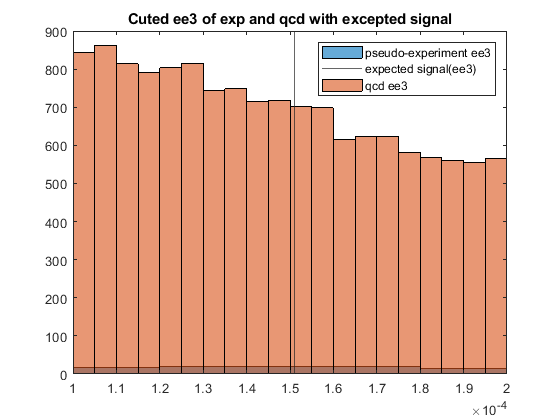

hold on
histogram(q_ee3_cut)
xlim([0.0001 0.0002])
title('Cuted ee3 of exp and qcd with excepted signal')
legend('pseudo-experiment ee3','expected signal(ee3)','qcd ee3')


h_counts = 0;
q_counts = 0;
for i = 1:length(low_ee3)
    if ismember(low_ee3(i),higgs_data)
        h_counts = h_counts+1;
    else if ismember(low_ee3(i),qcd_data)
            q_counts = q_counts+1;
        end
    end
end

significant = h_counts/sqrt(q_counts)

significant = 0.5787

%Based on the second grapg, we can see the excepted value line seperate
%background by half, therefore, its probability should be closed but a
%little higher than 0.5. That is pretty closed to significant value.



%For high lumi data
lambda = fitdist(higgs_data(6,:).','Poisson').lambda;
figure()
histogram(high_ee3)
hold on
xline(lambda)

ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 2.1114e-04
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


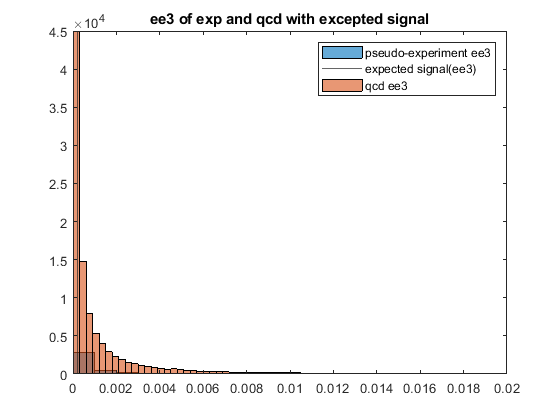

hold on
qcd_ee3 = qcd_data(6,:);
histogram(qcd_ee3)
xlim([0 0.02])
title('ee3 of exp and qcd with excepted signal')
legend('pseudo-experiment ee3','expected signal(ee3)','qcd ee3')


%Cut ee3 outside the range 0.0001 to 0.0002
high_ee3_cut = 0;
for i = 1:length(high_ee3)
    if high_ee3(i)>=0.0001 & high_ee3(i)<=0.0002
        high_ee3_cut = [high_ee3_cut;high_ee3(i)];
    end
end
high_ee3_cut = high_ee3_cut(2:end,:);

q_ee3_cut = 0;
for i = 1:length(qcd_ee3)
    if qcd_ee3(i)>=0.0001 & qcd_ee3(i)<=0.0002
        q_ee3_cut = [q_ee3_cut;qcd_ee3(i)];
    end
end
q_ee3_cut = q_ee3_cut(2:end,:);

higgs_ee3 = higgs_data(6,:);
h_ee3_cut = 0;
for i = 1:length(higgs_ee3)
    if higgs_ee3(i)>=0.0001 & higgs_ee3(i)<=0.0002
        h_ee3_cut = [h_ee3_cut;higgs_ee3(i)];
    end
end
h_ee3_cut = h_ee3_cut(2:end,:);

lambda = fitdist(h_ee3_cut,'Poisson').lambda;
figure()
histogram(high_ee3_cut)
hold on
xline(lambda)

ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 1.5095e-04
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


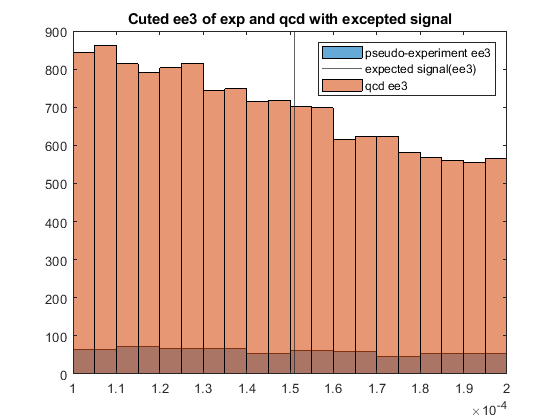

hold on
histogram(q_ee3_cut)
xlim([0.0001 0.0002])
title('Cuted ee3 of exp and qcd with excepted signal')
legend('pseudo-experiment ee3','expected signal(ee3)','qcd ee3')


h_counts = 0;
q_counts = 0;
for i = 1:length(high_ee3)
    if ismember(high_ee3(i),higgs_data)
        h_counts = h_counts+1;
    else if ismember(high_ee3(i),qcd_data)
            q_counts = q_counts+1;
        end
    end
end

significant = h_counts/sqrt(q_counts)

significant = 1.9265